clear
close all

%Change directory to data

current_script_Path = matlab.desktop.editor.getActiveFilename;
folder_of_current_script_Path = current_script_Path(1:end-24);
cd(folder_of_current_script_Path);
cd ../data/


## Run python script to extract hystory outputs

status = system('abaqus cae noGUI=../src/read_history_output.py')

Abaqus License Manager checked out the following license: 
"cae" from Flexnet server abaqus.license.strath.ac.uk 
<16 out of 22 licenses remain available>. 


status = 0

## Plot

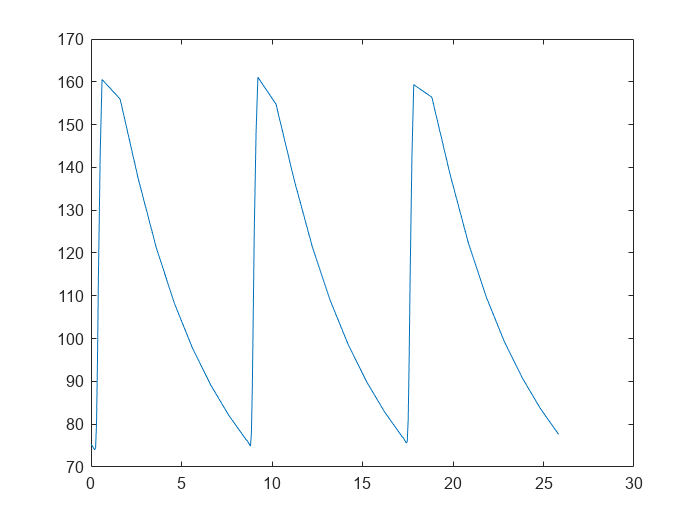




a=readmatrix('Temperature_Element_at_heigt_2.5.csv');

plot(a(:,1),a(:,2))

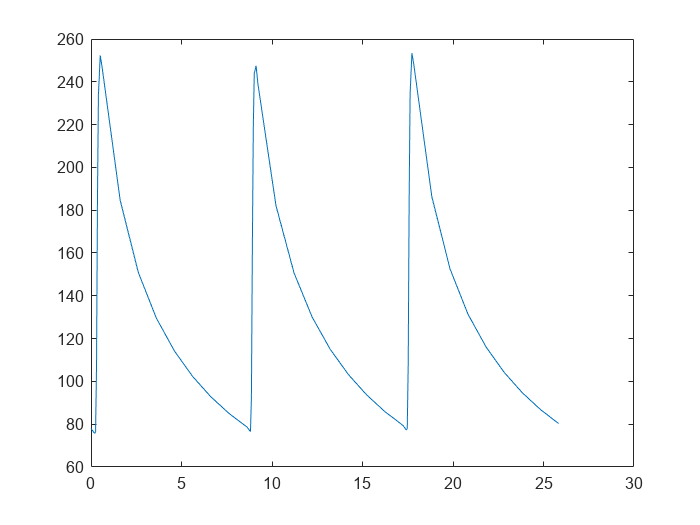




b=readmatrix('Temperature_Element_at_heigt_5.csv');

plot(b(:,1),b(:,2))